**AVD Group 01**

Hanchen Li

Note that all the **units** in equation are** imperial**

% House Keeping
clear
clc
close all

g = 9.80665;                          % Standard acceleration of gravity (m/s^2)

## **1. Weight Estimation**

### **1.1 Structures Group**

**Aircraft Wings**

% Basic Parameters

W_dg = 4.2990e5;                      % Design gross weight (kg)
W_dg = convmass(W_dg, 'kg', 'lbm');   % Design gross weight (lb)

N_z = 1.5 * 2.5;                      % Ultimate load factor (1.5 x limit load factor)

S_w = 548.7013;                       % Reference wing area (m^2)
S_w = convlength(S_w, 'm', 'ft');  
S_w = convlength(S_w, 'm', 'ft');     % Reference wing area (ft^2)

AR = 7.70;                            % Aspect Ratio

Taper = 0.2;                          % Wing taper ratio % Undefined

S_cs = 250;                           % Total control surface area (m^2) % Undefined
S_cs = convlength(S_cs, 'm', 'ft');  
S_cs = convlength(S_cs, 'm', 'ft');   % Total control surface area (ft^2)

S_csw = 140;                          % Area of wing mounted control surfaces (m^2) % Undefined
S_csw = convlength(S_csw, 'm', 'ft');  
S_csw = convlength(S_csw, 'm', 'ft'); % Area of wing mounted control surfaces (ft^2)

Sweep = 33.5;                         % Wing quarter chord sweep (degree) % Undefined
Sweep = deg2rad(Sweep);               % Wing quarter chord sweep (rad)

t_c_root = 0.13;                      % Wing root thickness to chord ratio % Undefined

B_w = 65;                             % Wing span (m)
B_w = convlength(B_w, 'm', 'ft');     % Wing span (ft)

L_D = 17.43;                          % Lift to drag ratio (at cruise?)

V_S = 69;                             % Landing stall speed (m/s) % Undefined
V_S = convvel(V_S, 'm/s', 'ft/s');    % Landing stall speed (ft/s)

% Calculation

W_w = 0.0051 * (((W_dg * N_z) ^ 0.557) * (S_w ^ 0.649) * (AR ^ 0.5) * ((1 + Taper) ^ 0.1) * (S_csw ^ 0.1)) ...
    / (cos(Sweep) * (t_c_root ^ 0.4));

W_w = convmass(W_w, 'lbm', 'kg')

W_w = 4.6011e+04


% Use advanced composites

% W_w = 0.78 * W_w

**Horizontal Tailplane**

% Basic Parameters

K_uht = 1.0;                          % 1.143 for all-moving tail % 1.0 otherwise

S_ht = 120;                           % Horizontal tailplane area (m^2) % Undefined
S_ht = convlength(S_ht, 'm', 'ft');  
S_ht = convlength(S_ht, 'm', 'ft');   % Horizontal tailplane area (ft^2)

L_ht = 30;                            % Length from wing AC to horizontal tailplane AC (m) % Undefined
L_ht = convlength(L_ht, 'm', 'ft');   % Length from wing AC to horizontal tailplane AC (ft)
K_y = 0.3 * L_ht;                     % Aircraft pitching radius of gyration

AR_h = 7.4;                           % Horizontal tailplane aspect Ratio

S_e = 65;                             % Elevator area (m^2)
S_e = convlength(S_e, 'm', 'ft');  
S_e = convlength(S_e, 'm', 'ft');     % Elevator area (ft^2)

F_w = 7.14;                           % Fuselage width at horizontal tail intersection (m)
F_w = convlength(F_w, 'm', 'ft');     % Fuselage width at horizontal tail intersection (ft)

B_ht = 30.4;                          % Horizontal tailplane span (m)
B_ht = convlength(B_ht, 'm', 'ft');   % Horizontal tailplane span (ft)

Sweep_ht = 35;                        % Horizontal tailplane quarter chord sweep (degree) % Undefined
Sweep_ht = deg2rad(Sweep_ht);         % Horizontal tailplane quarter chord sweep (rad)

% Calculation

W_ht = 0.0379 * (K_uht * (W_dg ^ 0.639) * (N_z ^ 0.1) * (S_ht ^ 0.75) * (K_y ^ 0.704) * (AR_h ^ 0.166) ...
    * (1 + S_e / S_ht) ^ 0.1) / ((1 + F_w / B_ht) ^ 0.25 * L_ht * cos(Sweep_ht));

W_ht = convmass(W_ht, 'lbm', 'kg')

W_ht = 5.1753e+03


% Use advanced composites

% W_ht = 0.75 * W_ht

**Vertical Tailplane**

% Basic Parameters

H_t_v = 0;                            % 0 for fuselage mounted horizontal % 1.0 for T-tail

S_vt = 80;                            % Vertical tailplane area (m^2) % Undefined
S_vt = convlength(S_vt, 'm', 'ft');  
S_vt = convlength(S_vt, 'm', 'ft');   % Vertical tailplane area (ft^2)

L_vt = 51;                            % Length from wing AC to vertical tailplane AC (m) % Undefined
L_vt = convlength(L_vt, 'm', 'ft');   % Length from wing AC to vertical tailplane AC (ft)
K_z = L_vt;                           % Aircraft yaw radius of gyration

AR_v = 1.75;                          % Vertical tailplane aspect Ratio

Sweep_vt = 40;                        % Vertical tailplane quarter chord sweep (degree) % Undefined
Sweep_vt = deg2rad(Sweep_vt);         % Vertical tailplane quarter chord sweep (rad)

t_c_root_v = 0.13;                    % Vertical tailplane root thickness to chord ratio % Undefined

% Calculation

W_vt = 0.0026 * (((1 + H_t_v) ^ 0.225) * (W_dg ^ 0.556) * (N_z ^ 0.536) * (S_vt ^ 0.5) * (K_z ^ 0.875) ...
    * (AR_v ^ 0.35)) / ((L_vt ^ 0.5) * cos(Sweep_vt) * (t_c_root_v ^ 0.5));

W_vt = convmass(W_vt, 'lbm', 'kg')

W_vt = 4.4419e+03


% Use advanced composites

% W_vt = 0.75 * W_vt

**Fuselage**

% Basic Parameters

K_door = 1.12;                        % Undefined                       
% 1.0 if no cargo door, 1.06 for one side cargo door % 1.12 for two side cargo doors
% 1.12 for aft clamshell door, 1.25 for two side and an aft clamshell cargo doors

K_Lg = 1.0;                           % 1.12 for fuselage mounted landing gear % 1.0 otherwise

S_f = 2100;                           % Fuselage wetted area (m^2) % Undefined

L_f = 72.7;                           % Total fuselage length (m) % Undefined
L_f = convlength(L_f, 'm', 'ft');     % Total fuselage length (ft)

L = 70;                               % Fuselage structual length (m) % Undefined
L = convlength(L, 'm', 'ft');         % Fuselage structual length (ft)

K_ws = 0.75 * ((1 + 2 * Taper) / (1 + Taper)) * B_w * tan(Taper) / L

K_ws = 0.1647


% Calculation

W_fus = 0.3280 * K_door * K_Lg * ((W_dg * N_z) ^ 0.5) * (L ^ 0.25) * (S_f ^ 0.302) ...
    * ((1 + K_ws) ^ 0.04) * (L_D ^ 0.1);

W_fus = convmass(W_fus, 'lbm', 'kg')

W_fus = 1.6500e+04


% Use advanced composites

% W_fus = 0.85 * W_fus

**Main Landing Gear**

% Basic Parameters

K_mp = 1.0;                           % 1.126 for kneeling main gear % 1.0 otherwise

W_l = 0.9 * W_dg;                     % Landing design gross weight (lb) % Need clarify

N_gear = 2.8;                         % Undefined                 
% Ratio of average total load applied to the main gear during landing to the max landing weight
% Typically 2.7-3 for commercial aircraft

N_l = 1.5 * N_gear;

L_m = 5.5;                            % Main landing gear length (m) % Undefined 
L_m = convlength(L_m, 'm', 'in');     % Main landing gear length (inches)

N_mw = 12;                            % Number of main wheels % Undefined

N_mss = 2;                            % Number of main gear shock struts % Undefined

% Calculation

W_mlg = 0.0106 * K_mp * (W_l ^ 0.888) * (N_l ^ 0.25) * (L_m ^ 0.4) * (N_mw ^ 0.321) ...
    * (V_S ^ 0.1) / (N_mss ^ 0.5);

W_mlg = convmass(W_mlg, 'lbm', 'kg')

W_mlg = 2.9516e+04


% Use advanced composites

% W_mlg = 0.88 * W_mlg

**Nose Landing Gear**

% Basic Parameters

K_np = 1.0;                           % 1.15 for kneeling nose-gear % 1.0 otherwise

L_n = 5.3;                            % Nose landing gear length (m) % Undefined 
L_n = convlength(L_n, 'm', 'in');     % Nose landing gear length (inches)

N_nw = 2;                             % Number of nose wheels % Undefined

% Calculation

W_nlg = 0.032 * K_np * (W_l ^ 0.646) * (N_l ^ 0.2) * (L_n ^ 0.5) * (N_nw ^ 0.45);

W_nlg = convmass(W_nlg, 'lbm', 'kg')

W_nlg = 2.5885e+03


% Use advanced composites

% W_nlg = 0.88 * W_nlg

### **1.2 Propulsion Group**

**Engine with Nacelle**

% Basic Parameters

N_en = 4;                             % Number of engines

W_en = 6125;                          % Engine dry weight (kg)
W_en = convmass(W_en, 'kg', 'lbm');   % Engine dry weight (lb)

% Calculatin

W_enc = 2.331 * 1 * 1.18 * W_en ^ 0.901;

convmass(W_enc,'lbm','kg')

ans = 6.5708e+03


W_enc_total = N_en * convmass(W_enc, 'lbm', 'kg')

W_enc_total = 2.6283e+04

**Naclle**

% Basic Parameters

% K_ng = 1.017;                         % 1.017 for pylon mounted nacelle % 1.0 otherwise % Undefined 

% N_Lt = 5.3;                           % Naclle length (m) % Undefined 
% N_Lt = convlength(N_Lt, 'm', 'ft');   % Naclle length (ft)

% N_w = 3;                              % Naclle width (m) % Undefined 
% N_w = convlength(N_w, 'm', 'ft');     % Naclle width (ft)

% S_n = 27;                             % Nacelle wetted area (m^2)
% S_n = convlength(S_n, 'm', 'ft');  
% S_n = convlength(S_n, 'm', 'ft');     % Nacelle wetted area (ft^2)

% Calculation

% W_inl = 0.6724 * K_ng * (N_Lt ^ 0.1) * (N_w ^ 0.294) * (N_z ^ 0.119) * (W_enc ^ 0.611) * (N_en ^ 0.984) * (S_n ^ 0.224);

% W_inl = convmass(W_inl, 'lbm', 'kg')

% Use advanced composites

% W_inl = 0.85 * W_inl

**Engine Controls**

% Basic Parameters

L_ec = 55;
% Total engine controls routing distance, engine to cockpit (m) 
L_ec = convlength(L_ec, 'm', 'ft');   % Total engine controls routing distance (ft)

% Calculation

W_ec = 5 * N_en + 0.8 * L_ec;

W_ec = convmass(W_ec, 'lbm', 'kg')

W_ec = 74.5511

**Engine (Pneumatic) Starter**

% Calculation

W_es = 49.19 * (N_en * W_en / 1e3) ^ 0.541;

W_es = convmass(W_es, 'lbm', 'kg')

W_es = 193.1191

**Fuel System**

% Basic Parameters

V_t = 280;                            % Total volume of fuel tanks (m^3) % Undefined 
V_t = V_t / 0.0037854118;             % Total volume of fuel tanks (gal)

N_t = 11;                             % Total number of fuel tanks % Undefined

V_p = 0;                              % Self sealing tank volume (m^3) % Undefined 
V_p = V_p / 0.0037854118;             % Self sealing tank volume (gal)

V_i = 280;                            % Integral fuel tank volume (m^3) % Undefined 
V_i = V_i / 0.0037854118;             % Integral fuel tank volume (gal)

% Calculation

W_fs = 2.405 * (V_t ^ 0.606) * (N_t ^ 0.5) * ((1 + V_p / V_t) / (1 + V_i / V_t));

W_fs = convmass(W_fs, 'lbm', 'kg')

W_fs = 1.6147e+03

### **1.3 Equipment Group**

**Flight Controls**

% Basic Parameters

N_f = 6;                              % Undefined
% Number of function performed by controls % Typically 4-7

N_m = 1;                              % Undefined
% Number of mechanical function performed by controls % Typically 0-2

% I_y = W_fc * (K_y ^ 2) / g;

% Calculation

syms Wfc

assume(Wfc > 0)

W_fc = double(solve(145.9 * ((N_f ^ 0.554) * (S_cs ^ 0.2) * (((Wfc * (K_y ^ 2) / g) * 1e-6) ^ 0.07)) / (1 + N_m / N_f) == Wfc, Wfc));

W_fc = convmass(W_fc, 'lbm', 'kg')

W_fc = 642.4823

clearvars Wfc

**Installed APU**

% Basic Parameters

W_APU = 425;                          % Uninstalled APU weight (kg) % Undefined
W_APU = convmass(W_APU, 'kg', 'lbm'); % Uninstalled APU weight (lb)

% Calculation

W_APUinst = 2.2 * W_APU;

W_APUinst = convmass(W_APUinst, 'lbm', 'kg')

W_APUinst = 935.0000

**Instruments**

% Basic Parameters

K_r = 1.0;                            % 1.133 for reciprocatiing engines % 1.0 otherwise

K_tp = 1.0;                           % 0.793 for turboprop % 1.0 otherwise

N_c = 4;                              % Number of crew

% Calculation

W_instr = 4.509 * K_r * K_tp * (N_c ^ 0.541) * N_en * ((L_f + B_w) ^ 0.5);

W_instr = convmass(W_instr, 'lbm', 'kg')

W_instr = 368.1119

**Hydraulic System**

% Calculation

W_hydr = 0.2673 * N_f * ((L_f + B_w) ^ 0.937);

W_hydr = convmass(W_hydr, 'lbm', 'kg')

W_hydr = 223.6017

**Electrical System**

% Basic Parameters

R_kva = 130;                          % Undefined
% System electrical rating (kVA) % typically 40-60 for transports

L_a = 57;                             % Undefined
% Electrical routing distance, generators to avionics to cockpit (m)
L_a = convlength(L_a, 'm', 'ft');     % Electrical routing distance (ft)

N_gen = N_en + 1;                     % Number of generators % typically = N_en

% Calculation

W_el = 7.291 * (R_kva ^ 0.782) * (L_a ^ 0.346) * (N_gen ^ 0.1);

W_el = convmass(W_el, 'lbm', 'kg')

W_el = 1.0679e+03

**Avionics**

% Basic Parameters

W_uav = 1300;                         % Undefined
% Uninstalled avionics weight (kg) % typically 800-1400 lb (363-635 kg)
W_uav = convmass(W_uav, 'kg', 'lbm'); % Uninstalled APU weight (lb)

% Calculation

W_av = 1.73 * W_uav ^ 0.983;

W_av = convmass(W_av, 'lbm', 'kg')

W_av = 1.9643e+03

**Furnishings**

% Basic Parameters

W_c = 500 * 17 + (12 + 4) * 13.6      % Maximum cargo weight (kg)

W_c = 8.7176e+03

W_c = convmass(W_c, 'kg', 'lbm');     % Maximum cargo weight (lb)

N_seat_eco = 430;                     % Number of economic seats
W_seat_eco = 20;                      % Weight of single economic seat (kg)
W_seat_eco = convmass(W_seat_eco, 'kg', 'lbm'); 
% Weight of single economic seat (lb)

N_seat_busi = 70;                     % Number of business seats
W_seat_busi = 60;                     % Weight of single business seat (kg)
W_seat_busi = convmass(W_seat_busi, 'kg', 'lbm'); 
% Weight of single business seat (lb)

N_seat_jump = 12;                     % Number of jump seats
W_seat_jump = 15;                     % Weight of single jump seat (kg)
W_seat_jump = convmass(W_seat_jump, 'kg', 'lbm'); 
% Weight of single jump seat (lb)

K_lav = 1.11;
% 1.11 for long range aircraft % 0.31 for short range aircraft
% 3.9 for business jet

K_buf = 5.68;
% 1.02 for short range % 5.68 for very long range

N_p = 500 + 12 + 4;                   % Total number of person onboard

% Calculation

W_furn = 0.0577 * (N_c ^ 0.1) * (W_c ^ 0.393) * (S_f ^ 0.75) + ...
    N_seat_eco * W_seat_eco + N_seat_busi * W_seat_busi + N_seat_jump * W_seat_jump + ...
    K_lav * (N_p ^ 1.33) + K_buf * (N_p ^ 1.12);

W_furn = convmass(W_furn, 'lbm', 'kg')

W_furn = 1.8284e+04

**Air-Conditioning**

% Basic Parameters

V_pr = 80;                            % Volume of pressurized sections (m^3) % Undefined
V_pr = convlength(V_pr, 'm', 'ft');
V_pr = convlength(V_pr, 'm', 'ft');
V_pr = convlength(V_pr, 'm', 'ft');   % Volume of pressurized sections (ft^3)

% Calculation

W_ac = 62.36 * (N_p ^ 0.25) * ((V_pr * 1e-3) ^ 0.604) ^ (W_uav ^ 0.1);

W_ac = convmass(W_ac, 'lbm', 'kg')

W_ac = 541.5787

**Anti-Icing System**

% Calculation

W_ai = 0.002 * W_dg;

W_ai = convmass(W_ai, 'lbm', 'kg')

W_ai = 859.8000

**Handling Gear**

% Calculation

W_hg = 3e-4  * W_dg;

W_hg = convmass(W_hg, 'lbm', 'kg')

W_hg = 128.9700

### **1.4 Fuel Tanks and Water Tank**

**Inner Wing Fuel Tanks**

W_f_in = 65000 * 2 % (kg)

W_f_in = 130000

**Outer Wing Fuel Tanks**

W_f_out = 25000 * 2 % (kg)

W_f_out = 50000

**Center Wing Fuel Tank**

W_f_centre = 90000 % (kg)

W_f_centre = 90000

**Trim Tank**

W_f_trim = 15000 % (kg)

W_f_trim = 15000

**Surge Tank**

W_f_surge = 5000 * 2 % (kg)

W_f_surge = 10000

**Water Tank**

%

### **1.5 Overall**

**Gross Weight**

% Calculation

W_0 = convmass(W_dg, 'lbm', 'kg')

W_0 = 429900

**Crew Weight**

% Calculation

W_crew = 500 * 82.8 + (12 + 4) * 79.4

W_crew = 4.2670e+04

**Payload Weight**

% Calculation

W_payload = convmass(W_c, 'lbm', 'kg')

W_payload = 8.7176e+03

**Empty Weight**

% Calculation

W_e = W_w + W_ht + W_vt + W_fus + W_mlg + W_nlg + W_enc_total + W_ec + W_es + W_fs + W_fc + ...
    W_APUinst + W_instr + W_hydr + W_el + W_av + W_furn + W_ac + W_ai + W_hg

W_e = 1.5741e+05


% Add 5% allowence
W_e = 1.05 * W_e % 3-10% at this point

W_e = 1.6528e+05

% Design empty weight is 181910 kg

**Fuel Weight**

% Calculation

W_f = W_0 - W_e - W_crew - W_payload

W_f = 2.1323e+05

% Design fuel weight is 196600 kg

## **2. CG Estimation**

### **2.1 Structures Group**

**Aircraft Wings**

x_w = 31

x_w = 31

z_w = 3.8

z_w = 3.8000

**Horizontal Tailplane**

x_ht = 65

x_ht = 65

z_ht = 3.7

z_ht = 3.7000

**Vertical Tailplane**

x_vt = 69

x_vt = 69

z_vt = 15.3

z_vt = 15.3000

**Fuselage**

x_fus = 37

x_fus = 37

z_fus = 3.8

z_fus = 3.8000

**Main Landing Gear**

x_mlg = 42

x_mlg = 42

z_mlg = -5.7

z_mlg = -5.7000

**Nose Landing Gear**

x_nlg = 31

x_nlg = 31

z_nlg = -5.7

z_nlg = -5.7000

### **2.2 Propulsion Group**

**Engine with Nacelle**

x_enc = 26

x_enc = 26

z_enc = 2.8

z_enc = 2.8000

**Naclle**

%

**Engine Controls**

x_ec = 6

x_ec = 6

z_ec = -0.2

z_ec = -0.2000

**Engine (Pneumatic) Starter**

x_es = 26

x_es = 26

z_es = 2.8

z_es = 2.8000

**Fuel System**

x_fs = 36

x_fs = 36

z_fs = 3.8

z_fs = 3.8000

### **2.3 Equipment Group**

**Flight Controls**

x_fc = 35

x_fc = 35

z_fc = 2.8

z_fc = 2.8000

**Installed APU**

x_APUinst = 70

x_APUinst = 70

z_APUinst = 1.8

z_APUinst = 1.8000

**Instruments**

x_instr = 5

x_instr = 5

z_instr = -1.2

z_instr = -1.2000

**Hydraulic System**

x_hydr = 35

x_hydr = 35

z_hydr = 2.8

z_hydr = 2.8000

**Electrical System**

x_el = 30

x_el = 30

z_el = 1

z_el = 1

**Avionics**

x_av = 6

x_av = 6

z_av = -2.2

z_av = -2.2000

**Furnishings**

x_furn = 35

x_furn = 35

z_furn = 2.8

z_furn = 2.8000

**Air-Conditioning**

x_ac = 35

x_ac = 35

z_ac = -2.2

z_ac = -2.2000

**Anti-Icing System**

x_ai = 31

x_ai = 31

z_ai = 2.8

z_ai = 2.8000

**Handling Gear**

x_hg = 0

x_hg = 0

z_hg = 0

z_hg = 0

### **2.4 Fuel Tanks**

**Inner Wing Fuel Tanks**

x_f_in = 31

x_f_in = 31

z_f_in = 3.8

z_f_in = 3.8000

**Outer Wing Fuel Tanks**

x_f_out = 33

x_f_out = 33

z_f_out = 3.8

z_f_out = 3.8000

**Center Wing Fuel Tank**

x_f_centre = 35

x_f_centre = 35

z_f_centre = 2.8

z_f_centre = 2.8000

**Trim Tank**

x_f_trim = 67

x_f_trim = 67

z_f_trim = 3.8

z_f_trim = 3.8000

**Surge Tank**

x_f_surge = 36

x_f_surge = 36

z_f_surge = 3.8

z_f_surge = 3.8000

### **2.5 Overall**

**Crew Weight**

x_crew = 36

x_crew = 36

z_crew = 3.8

z_crew = 3.8000

**Payload Weight**

x_payload = 36.5

x_payload = 36.5000

z_payload = 3.8

z_payload = 3.8000

**Empty Weight**

x_e = (W_w * x_w + W_ht * x_ht + W_vt * x_vt + W_fus * x_fus + W_mlg * x_mlg + W_nlg * x_nlg + ...
    W_enc_total * x_enc + W_ec * x_ec + W_es * x_es + W_fs * x_fs + ...
    W_fc * x_fc + W_APUinst * x_APUinst + W_instr * x_instr + W_hydr * x_hydr + ...
    W_el * x_el + W_av * x_av + W_furn * x_furn + W_ac * x_ac + W_ai * x_ai + W_hg * x_hg) ./ ...
    (W_w + W_ht + W_vt + W_fus + W_mlg + W_nlg + ...
    W_enc_total + W_ec + W_es + W_fs + ...
    W_fc + W_APUinst + W_instr + W_hydr + W_el + W_av + W_furn + W_ac + W_ai + W_hg)

x_e = 35.4071


z_e = (W_w * z_w + W_ht * z_ht + W_vt * z_vt + W_fus * z_fus + W_mlg * z_mlg + W_nlg * z_nlg + ...
    W_enc_total * z_enc + W_ec * z_ec + W_es * z_es + W_fs * z_fs + ...
    W_fc * z_fc + W_APUinst * z_APUinst + W_instr * z_instr + W_hydr * x_hydr + ...
    W_el * z_el + W_av * z_av + W_furn * z_furn + W_ac * z_ac + W_ai * z_ai + W_hg * z_hg) ./ ...
    (W_w + W_ht + W_vt + W_fus + W_mlg + W_nlg + ...
    W_enc_total + W_ec + W_es + W_fs + ...
    W_fc + W_APUinst + W_instr + W_hydr + W_el + W_av + W_furn + W_ac + W_ai + W_hg)

z_e = 1.7910

**Fuel Weight**

Load from nose to tail

x_f_ntt = (W_f_in * x_f_in + W_f_out * x_f_out + (W_f - (W_f_in + W_f_out)) * x_f_centre) ./ (W_f_in + W_f_out + (W_f - (W_f_in + W_f_out)))

x_f_ntt = 32.0923



z_f_ntt = (W_f_in * z_f_in + W_f_out * z_f_out + (W_f - (W_f_in + W_f_out)) * z_f_centre) ./ (W_f_in + W_f_out + (W_f - (W_f_in + W_f_out)))

z_f_ntt = 3.6442

Load from tail to nose

x_f_ttn = (W_f_trim * x_f_trim + W_f_centre * x_f_centre + ...
    W_f_out * x_f_out + (W_f - (W_f_trim + W_f_centre + W_f_out)) * x_f_in) ./ ...
    (W_f_trim + W_f_centre + W_f_out + (W_f - (W_f_trim + W_f_centre + W_f_out)))

x_f_ttn = 35.6898


z_f_ttn = (W_f_trim * z_f_trim + W_f_centre * z_f_centre + ...
    W_f_out * z_f_out + (W_f - (W_f_trim + W_f_centre + W_f_out)) * z_f_in) ./ ...
    (W_f_trim + W_f_centre + W_f_out + (W_f - (W_f_trim + W_f_centre + W_f_out)))

z_f_ttn = 3.3779

### **2.6 C.G - Envelope**

Surge tanks are not considered in this part, as they are used for overflo, not part of the main fuel burn sequence; used for overflow.

% Empty Weight with Fuel 
% Manually input in this part is required because it just simply quicker

x_load_e (1, 1) = x_e;
x_load_e (1, 2) = (W_e * x_e + W_f_in * x_f_in) ./ (W_e + W_f_in);
x_load_e (1, 3) = (W_e * x_e + W_f_in * x_f_in + W_f_out * x_f_out) ./ (W_e + W_f_in + W_f_out);
x_load_e (1, 4) = (W_e * x_e + W_f_in * x_f_in + W_f_out * x_f_out + ...
    (W_f - (W_f_in + W_f_out)) * x_f_centre) ./ (W_e + W_f_in + W_f_out + (W_f - (W_f_in + W_f_out)));
x_load_e (1, 5) = (W_e * x_e + W_f_trim * x_f_trim + W_f_centre * x_f_centre + ...
    W_f_out * x_f_out + (W_f - (W_f_trim + W_f_centre + W_f_out)) * x_f_in) ./ ...
    (W_e + W_f_trim + W_f_centre + W_f_out + (W_f - (W_f_trim + W_f_centre + W_f_out)));
x_load_e (1, 6) = (W_e * x_e + W_f_trim * x_f_trim + W_f_centre * x_f_centre + ...
    W_f_out * x_f_out) ./ (W_e + W_f_trim + W_f_centre + W_f_out);
x_load_e (1, 7) = (W_e * x_e + W_f_trim * x_f_trim + W_f_centre * x_f_centre) ...
    ./ (W_e + W_f_trim + W_f_centre);
x_load_e (1, 8) = (W_e * x_e + W_f_trim * x_f_trim) ./ (W_e + W_f_trim);
x_load_e (1, 9) = x_e

x_load_e =    35.4071   33.4669   33.3993   33.5398   35.5664   36.3966   37.0249   38.0357   35.4071



W_load_e (1, 1) = W_e;
W_load_e (1, 2) = W_e + W_f_in;
W_load_e (1, 3) = W_e + W_f_in + W_f_out;
W_load_e (1, 4) = W_e + W_f_in + W_f_out + (W_f - (W_f_in + W_f_out));
W_load_e (1, 5) = W_e + W_f_trim + W_f_centre + W_f_out + (W_f - (W_f_trim + W_f_centre + W_f_out));
W_load_e (1, 6) = W_e + W_f_trim + W_f_centre + W_f_out;
W_load_e (1, 7) = W_e + W_f_trim + W_f_centre;
W_load_e (1, 8) = W_e + W_f_trim;
W_load_e (1, 9) = W_e

W_load_e = 1.0e+05 *

    1.6528    2.9528    3.4528    3.7851    3.7851    3.2028    2.7028    1.8028    1.6528


% Empty Weight plus crew weight with Fuel 
x_load_c (1, 1) = (W_e * x_e + W_crew * x_crew) ./ (W_e + W_crew);
x_load_c (1, 2) = (W_e * x_e + W_crew * x_crew + W_f_in * x_f_in) ./ (W_e + W_crew + W_f_in);
x_load_c (1, 3) = (W_e * x_e + W_crew * x_crew + W_f_in * x_f_in + W_f_out * x_f_out) ./ (W_e + W_crew + W_f_in + W_f_out);
x_load_c (1, 4) = (W_e * x_e + W_crew * x_crew + W_f_in * x_f_in + W_f_out * x_f_out + ...
    (W_f - (W_f_in + W_f_out)) * x_f_centre) ./ (W_e + W_crew + W_f_in + W_f_out + (W_f - (W_f_in + W_f_out)));
x_load_c (1, 5) = (W_e * x_e + W_crew * x_crew + W_f_trim * x_f_trim + W_f_centre * x_f_centre + ...
    W_f_out * x_f_out + (W_f - (W_f_trim    + W_f_centre + W_f_out)) * x_f_in) ./ ...
    (W_e + W_crew + W_f_trim    + W_f_centre + W_f_out + (W_f - (W_f_trim + W_f_centre + W_f_out)));
x_load_c (1, 6) = (W_e * x_e + W_crew * x_crew + W_f_trim * x_f_trim + W_f_centre * x_f_centre + ...
    W_f_out * x_f_out) ./ (W_e + W_crew + W_f_trim    + W_f_centre + W_f_out);
x_load_c (1, 7) = (W_e * x_e + W_crew * x_crew + W_f_trim * x_f_trim + W_f_centre * x_f_centre) ...
    ./ (W_e + W_crew + W_f_trim    + W_f_centre);
x_load_c (1, 8) = (W_e * x_e + W_crew * x_crew + W_f_trim * x_f_trim) ./ (W_e + W_crew + W_f_trim);
x_load_c (1, 9) = (W_e * x_e + W_crew * x_crew) ./ (W_e + W_crew)

x_load_c =    35.5288   33.7867   33.6853   33.7890   35.6103   36.3499   36.8851   37.6461   35.5288



W_load_c (1, 1) = W_e + W_crew;
W_load_c (1, 2) = W_e + W_crew + W_f_in;
W_load_c (1, 3) = W_e + W_crew + W_f_in + W_f_out;
W_load_c (1, 4) = W_e + W_crew + W_f_in + W_f_out + (W_f - (W_f_in + W_f_out));
W_load_c (1, 5) = W_e + W_crew + W_f_trim + W_f_centre + W_f_out + (W_f - (W_f_trim + W_f_centre + W_f_out));
W_load_c (1, 6) = W_e + W_crew + W_f_trim + W_f_centre + W_f_out;
W_load_c (1, 7) = W_e + W_crew + W_f_trim + W_f_centre;
W_load_c (1, 8) = W_e + W_crew + W_f_trim;
W_load_c (1, 9) = W_e + W_crew

W_load_c = 1.0e+05 *

    2.0796    3.3796    3.8796    4.2118    4.2118    3.6296    3.1296    2.2296    2.0796


% Empty Weight plus crew weight plus payload weight with Fuel 
x_load_p (1, 1) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload) ./ (W_e + W_crew + W_payload);
x_load_p (1, 2) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_in * x_f_in) ./ (W_e + W_crew + W_payload + W_f_in);
x_load_p (1, 3) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_in * x_f_in + W_f_out * x_f_out) ./ (W_e + W_crew + W_payload + W_f_in + W_f_out);
x_load_p (1, 4) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_in * x_f_in + W_f_out * x_f_out + ...
    (W_f - (W_f_in + W_f_out)) * x_f_centre) ./ (W_e + W_crew + W_payload + W_f_in + W_f_out + (W_f - (W_f_in + W_f_out)));
x_load_p (1, 5) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + W_f_centre * x_f_centre + ...
    W_f_out * x_f_out + (W_f - (W_f_trim + W_f_centre + W_f_out)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + W_f_centre + W_f_out + (W_f - (W_f_trim + W_f_centre + W_f_out)));
x_load_p (1, 6) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + W_f_centre * x_f_centre + ...
    W_f_out * x_f_out) ./ (W_e + W_crew + W_payload + W_f_trim + W_f_centre + W_f_out);
x_load_p (1, 7) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + W_f_centre * x_f_centre) ...
    ./ (W_e + W_crew + W_payload + W_f_trim + W_f_centre);
x_load_p (1, 8) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim) ./ (W_e + W_crew + W_payload + W_f_trim);
x_load_p (1, 9) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload) ./ (W_e + W_crew + W_payload)

x_load_p =    35.5679   33.8549   33.7472   33.8440   35.6284   36.3535   36.8747   37.6030   35.5679



W_load_p (1, 1) = W_e + W_crew + W_payload;
W_load_p (1, 2) = W_e + W_crew + W_payload + W_f_in;
W_load_p (1, 3) = W_e + W_crew + W_payload + W_f_in + W_f_out;
W_load_p (1, 4) = W_e + W_crew + W_payload + W_f_in + W_f_out + (W_f - (W_f_in + W_f_out));
W_load_p (1, 5) = W_e + W_crew + W_payload + W_f_trim + W_f_centre + W_f_out + (W_f - (W_f_trim + W_f_centre + W_f_out));
W_load_p (1, 6) = W_e + W_crew + W_payload + W_f_trim + W_f_centre + W_f_out;
W_load_p (1, 7) = W_e + W_crew + W_payload + W_f_trim + W_f_centre;
W_load_p (1, 8) = W_e + W_crew + W_payload + W_f_trim;
W_load_p (1, 9) = W_e + W_crew + W_payload

W_load_p = 1.0e+05 *

    2.1667    3.4667    3.9667    4.2990    4.2990    3.7167    3.2167    2.3167    2.1667


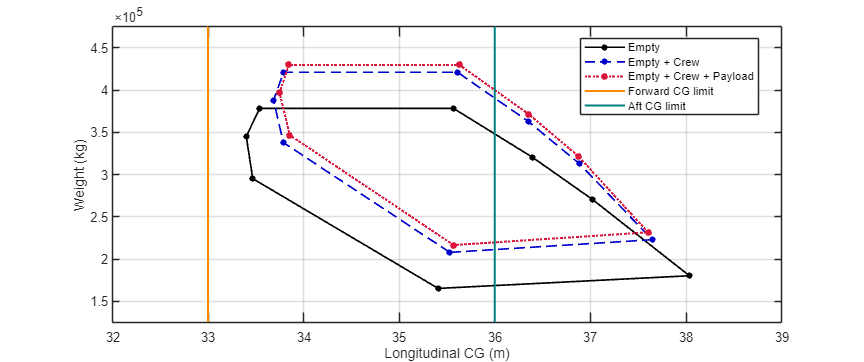


% Plot the C.G - envelope

figure(1)

clf;

plot(x_load_e, W_load_e, 'o-', 'Color',  [0/255 0/255 0/255], 'LineWidth', 1.25, 'Markersize', 3.5 , 'MarkerFaceColor', [0/255 0/255 0/255])
hold on % Empty
plot(x_load_c, W_load_c, 'o--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25, 'Markersize', 3.5 , 'MarkerFaceColor', [0/255 0/255 205/255]);
hold on % Empty + Crew
plot(x_load_p, W_load_p, 'o:', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5, 'Markersize', 3.5 , 'MarkerFaceColor', [220/255 20/255 60/255]);
hold on % Empty + Crew + Payload
plot([33 33], [0 5e5], '-', 'Color', [255/255 140/255 0/255], 'LineWidth', 1.5);
hold on % Forward C.G. limit % Undefined
plot([36 36], [0 5e5], '-', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5);
hold off % Aft C.G. limit % Undefined

legend('Empty', 'Empty + Crew', 'Empty + Crew + Payload',...
    'Forward CG limit', 'Aft CG limit', ...
       'Location', 'best', 'NumColumns', 1, FontSize = 8.5)

xlabel('Longitudinal CG (m)');
ylabel('Weight (kg)');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis

xlim([32 39]);
ylim([1.25e5 4.75e5]);

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 860 360]); % show plot with larger size 

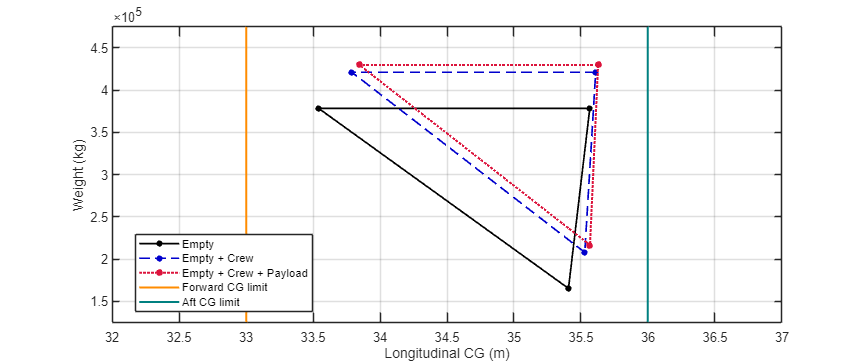

% Chose extreme case
x_load_e2 (1, 1) =  x_load_e (1, 1);
x_load_e2 (1, 2) =  x_load_e (1, 4);
x_load_e2 (1, 3) =  x_load_e (1, 5);
x_load_e2 (1, 4) =  x_load_e (1, 9);

W_load_e2 (1, 1) = W_load_e (1, 1);
W_load_e2 (1, 2) = W_load_e (1, 4);
W_load_e2 (1, 3) = W_load_e (1, 5);
W_load_e2 (1, 4) = W_load_e (1, 9);

x_load_c2 (1, 1) =  x_load_c (1, 1);
x_load_c2 (1, 2) =  x_load_c (1, 4);
x_load_c2 (1, 3) =  x_load_c (1, 5);
x_load_c2 (1, 4) =  x_load_c (1, 9);

W_load_c2 (1, 1) = W_load_c (1, 1);
W_load_c2 (1, 2) = W_load_c (1, 4);
W_load_c2 (1, 3) = W_load_c (1, 5);
W_load_c2 (1, 4) = W_load_c (1, 9);

x_load_p2 (1, 1) =  x_load_p (1, 1);
x_load_p2 (1, 2) =  x_load_p (1, 4);
x_load_p2 (1, 3) =  x_load_p (1, 5);
x_load_p2 (1, 4) =  x_load_p (1, 9);

W_load_p2 (1, 1) = W_load_p (1, 1);
W_load_p2 (1, 2) = W_load_p (1, 4);
W_load_p2 (1, 3) = W_load_p (1, 5);
W_load_p2 (1, 4) = W_load_p (1, 9);

% Plot the C.G - envelope

figure(2)

clf;

plot(x_load_e2, W_load_e2, 'o-', 'Color',  [0/255 0/255 0/255], 'LineWidth', 1.25, 'Markersize', 3.5 , 'MarkerFaceColor', [0/255 0/255 0/255])
hold on % Empty
plot(x_load_c2, W_load_c2, 'o--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25, 'Markersize', 3.5 , 'MarkerFaceColor', [0/255 0/255 205/255]);
hold on % Empty + Crew
plot(x_load_p2, W_load_p2, 'o:', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5, 'Markersize', 3.5 , 'MarkerFaceColor', [220/255 20/255 60/255]);
hold on % Empty + Crew + Payload
plot([33 33], [0 5e5], '-', 'Color', [255/255 140/255 0/255], 'LineWidth', 1.5);
hold on % Forward C.G. limit % Undefined
plot([36 36], [0 5e5], '-', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5);
hold off % Aft C.G. limit % Undefined

legend('Empty', 'Empty + Crew', 'Empty + Crew + Payload',...
    'Forward CG limit', 'Aft CG limit', ...
       'Location', 'best', 'NumColumns', 1, FontSize = 8.5)

xlabel('Longitudinal CG (m)');
ylabel('Weight (kg)');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis

xlim([32 37]);
ylim([1.25e5 4.75e5]);

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 860 360]); % show plot with larger size 

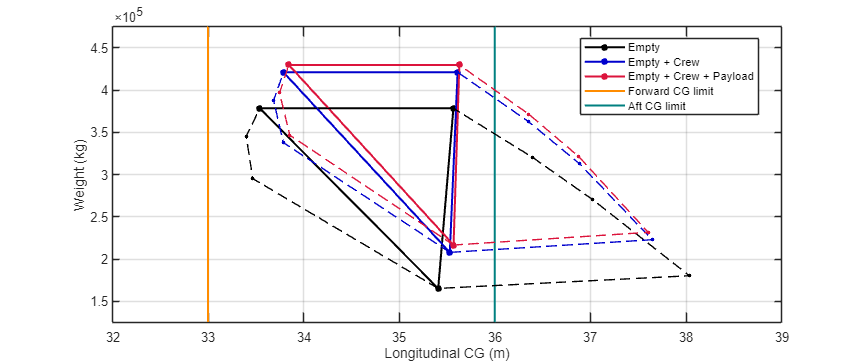

% Plot the C.G - envelope

figure(3)

clf;

plot(x_load_e2, W_load_e2, 'o-', 'Color',  [0/255 0/255 0/255], 'LineWidth', 1.5, 'Markersize', 3.5 , 'MarkerFaceColor', [0/255 0/255 0/255])
hold on % Empty
plot(x_load_c2, W_load_c2, 'o-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5, 'Markersize', 3.5 , 'MarkerFaceColor', [0/255 0/255 205/255]);
hold on % Empty + Crew
plot(x_load_p2, W_load_p2, 'o-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5, 'Markersize', 3.5 , 'MarkerFaceColor', [220/255 20/255 60/255]);
hold on % Empty + Crew + Payload
plot([33 33], [0 5e5], '-', 'Color', [255/255 140/255 0/255], 'LineWidth', 1.5);
hold on % Forward C.G. limit % Undefined
plot([36 36], [0 5e5], '-', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5);
hold on  % Aft C.G. limit % Undefined
plot(x_load_e, W_load_e, 'o--', 'Color',  [0/255 0/255 0/255], 'LineWidth', 0.25, 'Markersize', 2.5 , 'MarkerFaceColor', [0/255 0/255 0/255])
hold on % Empty
plot(x_load_c, W_load_c, 'o--', 'Color', [0/255 0/255 205/255], 'LineWidth', 0.25, 'Markersize', 2.5 , 'MarkerFaceColor', [0/255 0/255 205/255]);
hold on % Empty + Crew
plot(x_load_p, W_load_p, 'o--', 'Color', [220/255 20/255 60/255], 'LineWidth', 0.25, 'Markersize', 2.5 , 'MarkerFaceColor', [220/255 20/255 60/255]);
hold off % Empty + Crew + Payload

legend('Empty', 'Empty + Crew', 'Empty + Crew + Payload',...
    'Forward CG limit', 'Aft CG limit', ...
       'Location', 'best', 'NumColumns', 1, FontSize = 8.5)


xlabel('Longitudinal CG (m)');
ylabel('Weight (kg)');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis

xlim([32 39]);
ylim([1.25e5 4.75e5]);

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 860 360]); % show plot with larger size 

### **2.7 C.G - Mission Profile**

**Order of fuel burning:**

- Outer wing fuel tank - burned first to reduce wing bending moment

- Center (wing) fuel tank - to maintain a stable CG

- Inner wing fuel tank - burned later in the flight as fuel levels reduce

where trim tank is used dynamically to adjust CG as needed during flight

**Fuel fraction**

% This can be redone after design finish by fuel fraction codes
W_i = load('W_i.mat');
W_i = W_i.W_i;

Fuel useage in mission profile

W_f_mission = load('W_f.mat');
W_f_mission = W_f_mission.W_f;

W_f_use_mission (1, 1) = 0;
W_f_use_mission (1, 2) = W_0 - W_0 * W_i(1);
W_f_use_mission (1, 3) = W_0 - W_0 * W_i(1) * W_i(2);
W_f_use_mission (1, 4) = W_0 - W_0 * W_i(1) * W_i(2) * W_i(3);
W_f_use_mission (1, 5) = W_0 - W_0 * W_i(1) * W_i(2) * W_i(3) * W_i(4);
W_f_use_mission (1, 6) = W_0 - W_0 * W_i(1) * W_i(2) * W_i(3) * W_i(4) * W_i(5);
W_f_use_mission (1, 7) = W_0 - W_0 * W_i(1) * W_i(2) * W_i(3) * W_i(4) * W_i(5) * W_i(6);
W_f_use_mission (1, 8) = W_0 - W_0 * W_i(1) * W_i(2) * W_i(3) * W_i(4) * W_i(5) * W_i(6) * W_i(7);
W_f_use_mission (1, 9) = W_0 - W_0 * W_i(1) * W_i(2) * W_i(3) * W_i(4) * W_i(5) * W_i(6) * W_i(7) * W_i(8);
W_f_use_mission (1, 10) = W_0 - W_0 * W_i(1) * W_i(2) * W_i(3) * W_i(4) * W_i(5) * W_i(6) * W_i(7) * W_i(8) * W_i(9)

W_f_use_mission = 1.0e+05 *

         0    0.1290    0.1915    1.7538    1.7792    1.8035    1.8729    1.9122    1.9276    1.9465


**Without trim tank**

**0** Take-off Gross Weight

% Outer Wing Fuel Tank is empty in this case
% But need to be adjust after finalise the design

x_f_mission_centre (1, 1) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_in * x_f_in + (W_f - W_f_in) * x_f_centre) ./ ...
    (W_e + W_crew + W_payload + W_f_in + (W_f - W_f_in));

W_f_mission_centre (1, 1) = W_e + W_crew + W_payload + W_f_in + (W_f - W_f_in);

**0-1** Taxi & Takeoff

% Centre Wing Fuel Tank

x_f_mission_centre (1, 2) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_in * x_f_in + (W_f - W_f_in - W_f_use_mission (1, 2)) * x_f_centre) ./ ...
    (W_e + W_crew + W_payload + W_f_in + (W_f - W_f_in - W_f_use_mission (1, 2))); 

W_f_mission_centre (1, 2) = W_e + W_crew + W_payload + W_f_in + (W_f - W_f_in - W_f_use_mission (1, 2));

**1-2** Climb and accelerate to cruise

% Centre Wing Fuel Tank

x_f_mission_centre (1, 3) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_in * x_f_in + (W_f - W_f_in - W_f_use_mission (1, 3)) * x_f_centre) ./ ...
    (W_e + W_crew + W_payload + W_f_in + (W_f - W_f_in - W_f_use_mission (1, 3))) 

x_f_mission_centre =    34.0766   34.0481   34.0336



W_f_mission_centre (1, 3) = W_e + W_crew + W_payload + W_f_in + (W_f - W_f_in - W_f_use_mission (1, 3))

W_f_mission_centre = 1.0e+05 *

    4.2990    4.1700    4.1075


**2-3** Cruise for an air distance of 7500 nmi at Mach 0.83

% Inner Wing Fuel Tank

x_f_mission_in (1, 1) = x_f_mission_centre (1, 3);

W_f_mission_in (1, 1) = W_f_mission_centre (1, 3);

x_f_mission_in (1, 2) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + (W_f - W_f_use_mission (1, 4)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 4))); 

W_f_mission_in (1, 2) = W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 4));

**3-4** Descent to land

% Inner Wing Fuel Tank

x_f_mission_in (1, 3) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + (W_f - W_f_use_mission (1, 5)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 5))); 

W_f_mission_in (1, 3) = W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 5));

**4-5** Missed approach, followed by clmb and accelerate to alternate

% Inner Wing Fuel Tank

x_f_mission_in (1, 4) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + (W_f - W_f_use_mission (1, 6)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 6)));

W_f_mission_in (1, 4) = W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 6));

**5-6** Cruise to alternate destination 370 km away

% Inner Wing Fuel Tank

x_f_mission_in (1, 5) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + (W_f - W_f_use_mission (1, 7)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 7))); 

W_f_mission_in (1, 5) = W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 7));

**6-7** Loiter at 5000 ft for 45 minutes

% Inner Wing Fuel Tank

x_f_mission_in (1, 6) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + (W_f - W_f_use_mission (1, 8)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 8)));

W_f_mission_in (1, 6) = W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 8));

**7-8** Descent to land

% Inner Wing Fuel Tank

x_f_mission_in (1, 7) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + (W_f - W_f_use_mission (1, 9)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 9)));

W_f_mission_in (1, 7) = W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 9));

**8-9** Landing & Taxi

% Inner Wing Fuel Tank

x_f_mission_in (1, 8) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + (W_f - W_f_use_mission (1, 9)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 10))) 

x_f_mission_in =    34.0336   34.8886   34.9278   34.9661   35.0795   35.1467   35.1736   35.4572



W_f_mission_in (1, 8) = W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 10))

W_f_mission_in = 1.0e+05 *

    4.1075    2.5452    2.5198    2.4955    2.4261    2.3868    2.3714    2.3525


**With trim tank**

**0** Take-off Gross Weight

% Outer Wing Fuel Tank is empty in this case
% But need to be adjust after finalise the design

x_f_mission_centre2 (1, 1) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + W_f_in * x_f_in + (W_f - W_f_in) * x_f_centre) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + W_f_in + (W_f - W_f_trim - W_f_in));

W_f_mission_centre2 (1, 1) = W_e + W_crew + W_payload + W_f_trim + W_f_in + (W_f - W_f_trim - W_f_in);

**0-1** Taxi & Takeoff

% Centre Wing Fuel Tank

x_f_mission_centre2 (1, 2) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + W_f_in * x_f_in + (W_f - W_f_trim - W_f_in - W_f_use_mission (1, 2)) * x_f_centre) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + W_f_in + (W_f - W_f_trim - W_f_in - W_f_use_mission (1, 2))); 

W_f_mission_centre2 (1, 2) = W_e + W_crew + W_payload + W_f_trim + W_f_in + (W_f - W_f_trim - W_f_in - W_f_use_mission (1, 2));

**1-2** Climb and accelerate to cruise

% Centre Wing Fuel Tank

x_f_mission_centre2 (1, 3) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + W_f_in * x_f_in + (W_f - W_f_trim - W_f_in - W_f_use_mission (1, 3)) * x_f_centre) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + W_f_in + (W_f - W_f_trim - W_f_in - W_f_use_mission (1, 3))) 

x_f_mission_centre2 =    36.4144   35.1991   35.2022



W_f_mission_centre2 (1, 3) = W_e + W_crew + W_payload + W_f_trim + W_f_in + (W_f - W_f_trim - W_f_in - W_f_use_mission (1, 3))

W_f_mission_centre2 = 1.0e+05 *

    4.2990    4.1700    4.1075


**2-3** Cruise for an air distance of 7500 nmi at Mach 0.83

% Inner Wing Fuel Tank

x_f_mission_in2 (1, 1) = x_f_mission_centre2 (1, 3);

W_f_mission_in2 (1, 1) = W_f_mission_centre2 (1, 3);

x_f_mission_in2 (1, 2) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 4)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 4))); 

W_f_mission_in2 (1, 2) = W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 4));

**3-4** Descent to land

% Inner Wing Fuel Tank

x_f_mission_in2 (1, 3) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 5)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 5))); 

W_f_mission_in2 (1, 3) = W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 5));

**4-5** Missed approach, followed by clmb and accelerate to alternate

% Inner Wing Fuel Tank

x_f_mission_in2 (1, 4) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 6)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 6)));

W_f_mission_in2 (1, 4) = W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 6));

**5-6** Cruise to alternate destination 370 km away

% Inner Wing Fuel Tank

x_f_mission_in2 (1, 5) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 7)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 7))); 

W_f_mission_in2 (1, 5) = W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 7));

**6-7** Loiter at 5000 ft for 45 minutes

% Inner Wing Fuel Tank

x_f_mission_in2 (1, 6) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 8)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 8)));

W_f_mission_in2 (1, 6) = W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 8));

**7-8** Descent to land

% Inner Wing Fuel Tank

x_f_mission_in2 (1, 7) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 9)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 9)));

W_f_mission_in2 (1, 7) = W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 9));

**8-9** Landing & Taxi

% Inner Wing Fuel Tank

x_f_mission_in2 (1, 8) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 9)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 10))) 

x_f_mission_in2 =    35.2022   37.0102   37.0709   37.1300   37.3052   37.4092   37.4507   37.7527



W_f_mission_in2 (1, 8) = W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 10))

W_f_mission_in2 = 1.0e+05 *

    4.1075    2.5452    2.5198    2.4955    2.4261    2.3868    2.3714    2.3525


**Plot the C.G - mission profile**

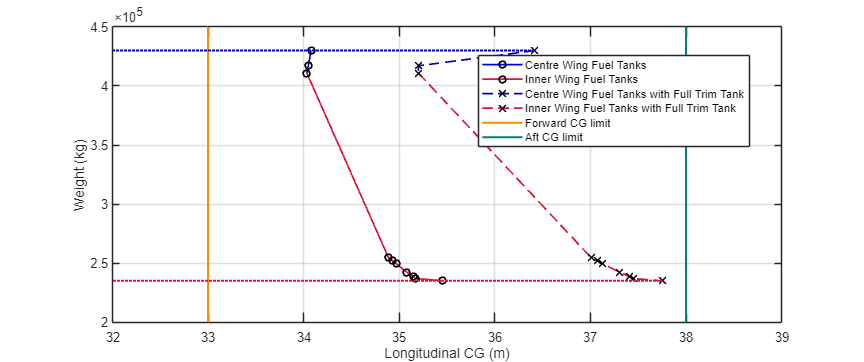

figure(4)

clf;

plot(x_f_mission_centre, W_f_mission_centre, 'o-', 'Color',  [0/255 0/255 205/255], 'LineWidth', 1.25, 'Markersize', 5 , 'MarkerEdgeColor', [0/255 0/255 0/255])
hold on % Centre Wing Fuel Tank without trim tank
plot(x_f_mission_in, W_f_mission_in, 'o-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.25, 'Markersize', 5 , 'MarkerEdgeColor', [0/255 0/255 0/255]);
hold on % Inner Wing Fuel Tank without trim tank
plot(x_f_mission_centre2, W_f_mission_centre2, 'x--', 'Color',  [0/255 0/255 205/255], 'LineWidth', 1.25, 'Markersize', 7 , 'MarkerEdgeColor', [0/255 0/255 0/255])
hold on % Centre Wing Fuel Tank without trim tank
plot(x_f_mission_in2, W_f_mission_in2, 'x--', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.25, 'Markersize', 7 , 'MarkerEdgeColor', [0/255 0/255 0/255]);
hold on % Inner Wing Fuel Tank without trim tank
plot([33 33], [0 5e5], '-', 'Color', [255/255 140/255 0/255], 'LineWidth', 1.5);
hold on % Forward C.G. limit % Undefined
plot([38 38], [0 5e5], '-', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5);
hold on % Aft C.G. limit % Undefined
plot([0 x_f_mission_centre2(1)], [W_f_mission_centre(1) W_f_mission_centre(1)], ':', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5);
hold on % W_0
plot([0 x_f_mission_in2(end)], [W_f_mission_in(end) W_f_mission_in(end)], ':', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5);
hold on % W_land % Undefined

legend('Centre Wing Fuel Tanks', 'Inner Wing Fuel Tanks', ...
    'Centre Wing Fuel Tanks with Full Trim Tank', 'Inner Wing Fuel Tanks with Full Trim Tank', ...
    'Forward CG limit', 'Aft CG limit', ...
       'Location', 'best', 'NumColumns', 1, FontSize = 8.5)

xlabel('Longitudinal CG (m)');
ylabel('Weight (kg)');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis

xlim([32 39]);
ylim([2e5 4.5e5]);

grid on;                             % set the grid of the graph

set(gcf, 'Position', [0 0 860 360]); % show plot with larger size 